# Developing the Preprocessing and Feature Extracting Workflow

## 1. Removing Quiet Parts of the Signal

%Loading the 3rd signal of patient 42
[signal1, sampleRate1] = audioread("pat_22.wav");
fprintf("Sample Rate = %d", sampleRate1)

Sample Rate = 44100

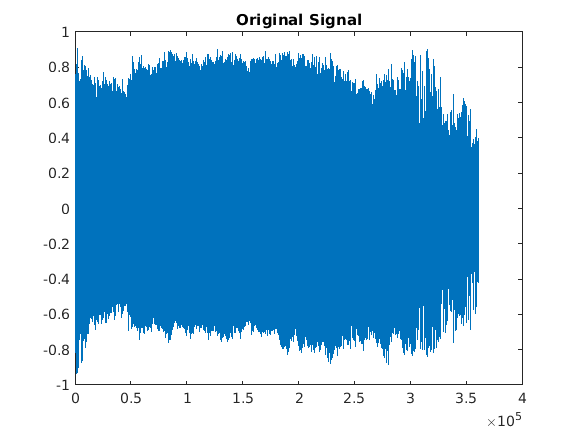

%Plotting the signal
plot(signal1)
title("Original Signal")

%Specifying frame size before removing silent areas
frameDuration = 25e-03

frameDuration = 0.0250

frameSize = floor(frameDuration * sampleRate1)

frameSize = 1102

numFrames = floor(length(signal1)/frameSize)

numFrames = 328

fprintf("Total number of frames = %d", numFrames*frameSize)

Total number of frames = 361456

%Make a copy of signal1
oldSignal = signal1(:);

%Initialize signal1 to an array of zeros
signal1 = zeros([length(oldSignal) 1]);
discarded = zeros([numFrames, 1]);

%Copying only frames with max amplitude above threshold amplitude in
%oldSignal to signal1
count = 0;
for i = 1:numFrames
    frame = oldSignal((i-1)*frameSize + 1 : i*frameSize);
    maxVal = max(frame);
    
    if maxVal>0.03  %frame has max value above threshold
        count = count+1;
        signal1((count-1)*frameSize + 1 : count*frameSize) = frame(:);
    else
       discarded(i) = 1; 
    end
end

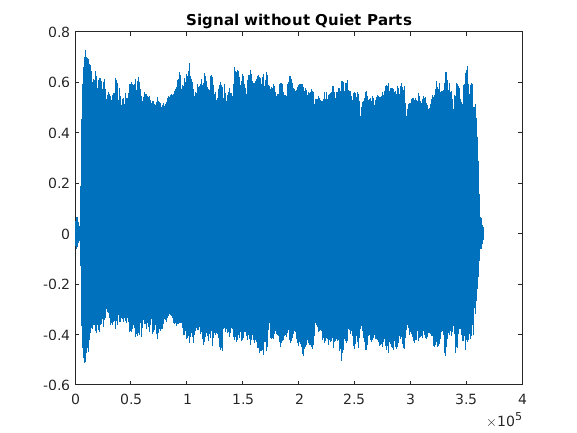

%Truncating at unused part of the signal array
signal1 = signal1(1 : frameSize*count);
plot(signal1)
title("Signal without Quiet Parts")

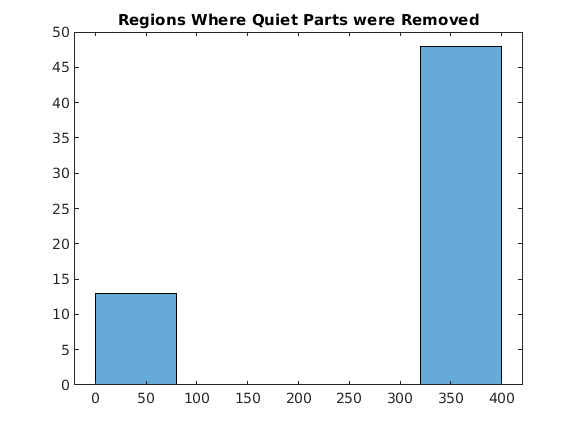

discardIndex = find(discarded);
histogram(discardIndex, 5)
title("Regions Where Quiet Parts were Removed")

fprintf("number of frames removed = %d", numFrames - count)

number of frames removed = 61

preEmphCoeff = [1 -0.95];
filteredBeforeSmoothing = filter(preEmphCoeff, 1, signal1);
filteredBeforeSmoothing = smoothdata(filteredBeforeSmoothing,'gaussian',4);

## 2.  Smoothing the Signal

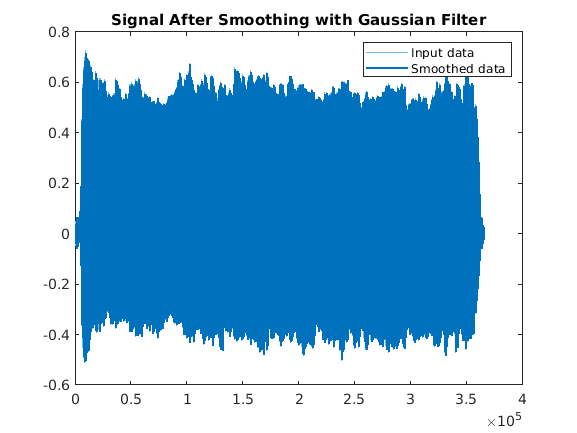

% Smooth input data
smoothedData = smoothdata(signal1,'gaussian',4);

% Display results
clf
plot(signal1,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(smoothedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend
title("Signal After Smoothing with Gaussian Filter")

## 3. Applying Pre-emphasis on the Signal

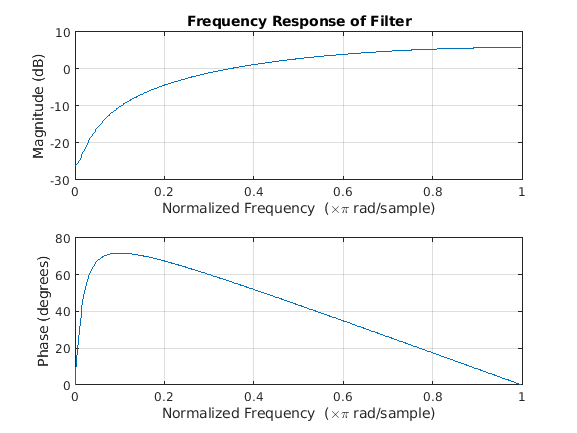

preEmphCoeff = [1 -0.95];
freqz(preEmphCoeff);
zoom on; grid on;
title("Frequency Response of Filter");

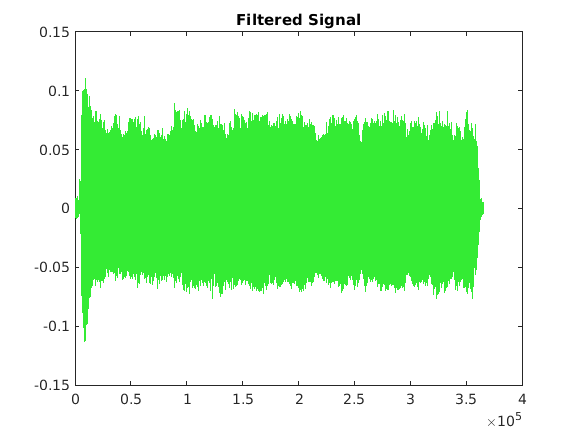

%Applying this filter on the signal:
filtered = filter(preEmphCoeff, 1, signal1);
smoothedAndFiltered = filter(preEmphCoeff, 1, smoothedData);

%Temp
twiceFilteredAfterSmoothing = filter(preEmphCoeff, 1, smoothedAndFiltered);
%Temp

plot(filtered, 'Color', [52, 235, 52]/255);
title("Filtered Signal");

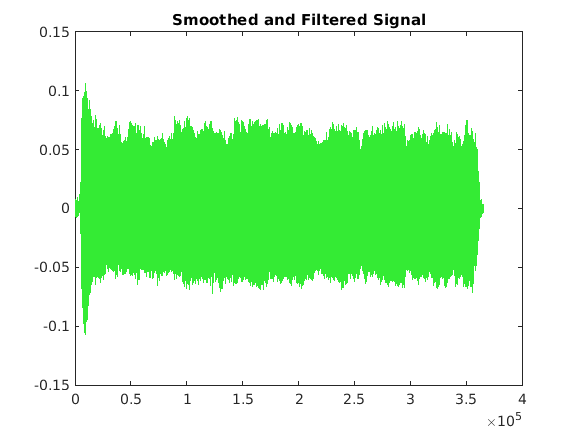

plot(smoothedAndFiltered, 'Color', [52, 235, 52]/255);
title("Smoothed and Filtered Signal");

## 3. Obtaining Frequency and Time Domain features

### Visualizing the Spectrogram

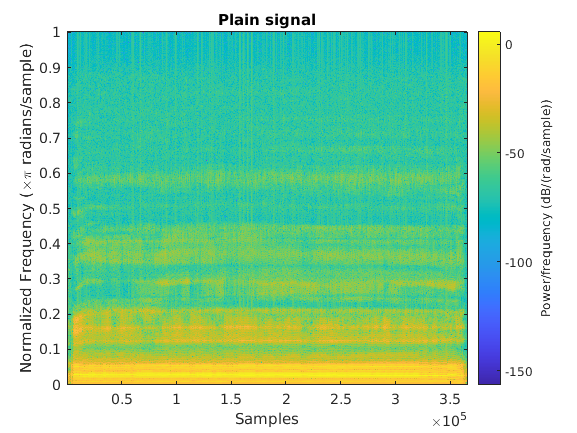

spectrogram(signal1, hamming(1024), 512, 1024, 'yaxis')
title("Plain signal");

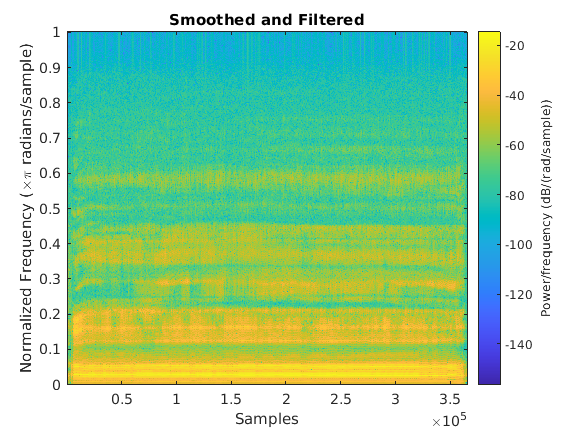

spectrogram(smoothedAndFiltered, hamming(1024), 512, 1024, 'yaxis')
title("Smoothed and Filtered");

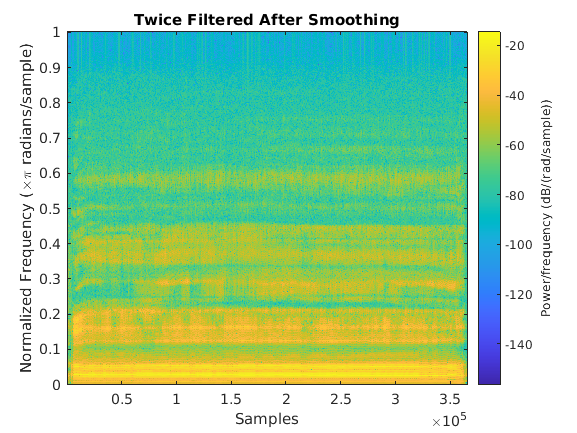

spectrogram(smoothedAndFiltered, hamming(1024), 512, 1024, 'yaxis')
title("Twice Filtered After Smoothing");

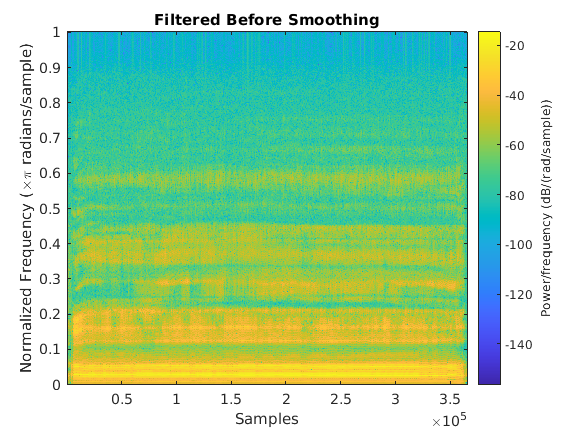

spectrogram(filteredBeforeSmoothing, hamming(1024), 512, 1024, 'yaxis')
title("Filtered Before Smoothing");

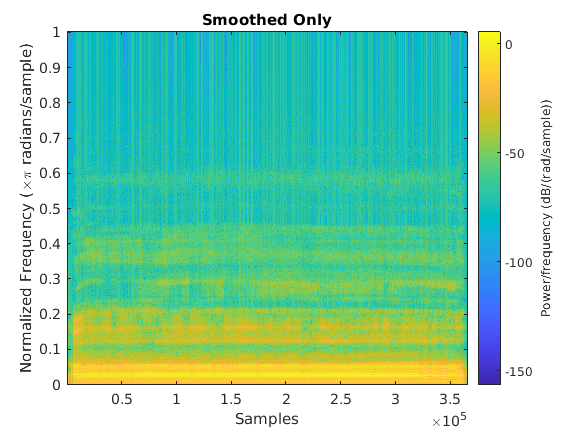

spectrogram(smoothedData, hamming(1024), 512, 1024, 'yaxis')
title("Smoothed Only");

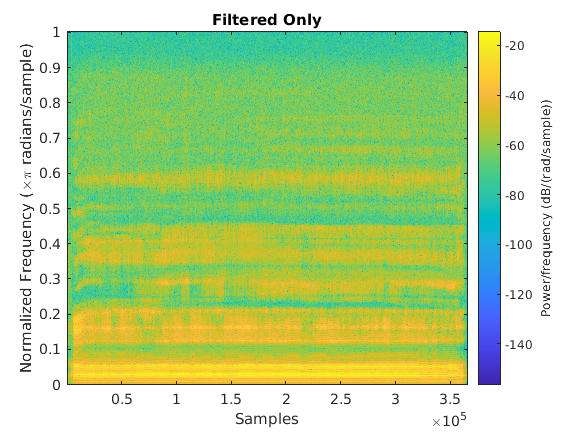

spectrogram(filtered, hamming(1024), 512, 1024, 'yaxis')
title("Filtered Only");

### Mel Frequency Cepstral Coefficients (unused)

coeffs = mfcc(smoothedAndFiltered, sampleRate1, "Window", hamming(1024), "OverlapLength", 512, "NumCoeffs", 13)

coeffs =    -5.8729  -19.7492    0.8727    1.3830    0.1866   -0.0103    0.9057   -0.1874   -0.8236   -0.6986   -0.3697    0.2751   -0.0559   -0.0347
   -5.2267  -18.8080    1.3228    1.2756    0.0682   -0.3147    0.6790   -0.3409   -1.4523   -0.4170    0.0386    0.6593   -0.2316    0.1900
   -5.0107  -18.6653    1.2606    0.8621    0.2338   -0.4955    0.4000   -0.6024   -1.2173   -0.4498    0.0914    0.5530   -0.0368    0.1637
   -5.0731  -18.5398    1.4845    0.8275    0.0884   -0.5777    0.5524   -0.5728   -1.2812   -0.4018    0.0604    0.6629    0.0274   -0.0079
   -5.4179  -18.7750    1.5440    0.3155   -0.1889   -0.4316    0.5585   -0.3925   -1.1190   -0.1844    0.0920    0.5154    0.0020   -0.0333
   -5.9579  -19.1364    1.5475    0.8241   -0.3166   -0.2377    0.4611   -0.4443   -0.7337    0.2730    0.4625    0.4417   -0.1095   -0.0975
   -6.3665  -19.6923    1.4384    0.7437   -0.6379   -0.3252    0.6984   -0.4150   -0.6824    0.1795    0.1741    0.4186   -0.0359   -0.0456
   -

### Obtaining all Features Using the Live Task

% Create and set up an audioFeatureExtractor object
extractor = audioFeatureExtractor("SampleRate",sampleRate1, ...
    "linearSpectrum",true,"melSpectrum",true, ...
    "barkSpectrum",true,"erbSpectrum",true, ...
    "mfcc",true,"mfccDelta",true, ...
    "mfccDeltaDelta",true,"gtcc",true, ...
    "gtccDelta",true,"gtccDeltaDelta",true, ...
    "spectralCentroid",true,"spectralCrest",true, ...
    "spectralDecrease",true,"spectralEntropy",true, ...
    "spectralFlatness",true,"spectralFlux",true, ...
    "spectralKurtosis",true,"spectralRolloffPoint",true, ...
    "spectralSkewness",true,"spectralSlope",true, ...
    "spectralSpread",true,"pitch",true, ...
    "harmonicRatio",true);

% Extract features from audio data
features = extract(extractor,smoothedAndFiltered);

% Display output summary
info(extractor)

   Output column mapping

            linearSpectrum: 1:513
               melSpectrum: 514:545
              barkSpectrum: 546:577
               erbSpectrum: 578:620
                      mfcc: 621:633
                 mfccDelta: 634:646
            mfccDeltaDelta: 647:659
                      gtcc: 660:672
                 gtccDelta: 673:685
            gtccDeltaDelta: 686:698
          spectralCentroid: 699
             spectralCrest: 700
          spectralDecrease: 701
           spectralEntropy: 702
          spectralFlatness: 703
              spectralFlux: 704
          spectralKurtosis: 705
      spectralRolloffPoint: 706
          spectralSkewness: 707
             spectralSlope: 708
            spectralSpread: 709
                     pitch: 710
             harmonicRatio: 711


%Printing the size occuoied by the workspace just out of curiousity
fprintf("Size of workspace = %d MB", int16(sum(struct2table(whos).('bytes'))/2^20))

Size of workspace = 24 MB

%Separating features into ones which have a single value for a given frame
%and ones with multiple parameters for a single frame.
%
%If we decide to include the mean of the single value features separately
%by concatenating the values to the result of a CNN, we can use this
%separated set of features.
SpectralAndCepstralFeatures = features(:, 1:698)

SpectralAndCepstralFeatures =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.000

LinearSpectrumDescriptorFeatures = features(:, 699:end)

LinearSpectrumDescriptorFeatures = 	1.0e+03 *

    2.8194    0.0665    0.0001    0.0007    0.0000         0    0.0037    7.9242    0.0010   -0.0000    2.8025    0.1260    0.0002
    1.8829    0.1329    0.0001    0.0005    0.0000    0.0000    0.0062    7.1490    0.0018   -0.0000    2.2454    0.1396    0.0004
    1.7235    0.1323    0.0001    0.0005    0.0000    0.0000    0.0083    6.2877    0.0021   -0.0000    2.0465    0.1361    0.0005
    1.5641    0.1342    0.0001    0.0005    0.0000    0.0000    0.0102    5.8570    0.0024   -0.0000    1.9364    0.1365    0.0005
    1.9216    0.0870    0.0001    0.0006    0.0000    0.0000    0.0088    7.1921    0.0023   -0.0000    2.2874    0.1400    0.0004
    1.9879    0.0487    0.0001    0.0007    0.0000    0.0000    0.0075    7.7520    0.0020   -0.0000    2.5357    0.1542    0.0003
    2.4600    0.0492    0.0001    0.0007    0.0000    0.0000    0.0065    8.2688    0.0018   -0.0000    2.7676    0.1664    0.0003
    2.9750    0.0456    0.0001    0.

## 4. Normalizing Features

%Normalizing Spectral and Cepstral Features
%
%Somw of the fearures are multi-column features (eg. linearSpectrum,
%melSpectrum and all the remaining features in the Spectral and Cepstral
%features matrix
%
%As the normalize() function does not normalize multiple columns together
%we use the CustomNormalize() function as defined at the end of the script
SpectralAndCepstralFeatures_normalized = CustomNormalize(SpectralAndCepstralFeatures, [1 514 546 578 621 634 647 660 673 686 699])

feature number : 10

SpectralAndCepstralFeatures_normalized =     0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0002    0.0001    0.0004    0.0009    0.0005    0.0008    0.0015    0.0004    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0002    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0001    0.0002    0.0001    0.0007    0.0005    0.0001    0.0006    0.0014    0.0009    0.0013    0.0076    0.0037    0.0001    0.0005    0.0001    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0011    0.0009    0.0000    0.0002    0.0001    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.00

%Normalizing the spectral descriptor features (the features which have only
%one value for a given frame
LinearSpectrumDescriptorFeatures_normalized = CustomNormalize(LinearSpectrumDescriptorFeatures, [1:13 14])

feature number : 13

LinearSpectrumDescriptorFeatures_normalized =     0.9279    0.1132    0.2969    0.8732    0.4090         0         0    0.8525         0    0.9986    0.8227    0.2906    0.0342
    0.4941    0.4724    0.4814    0.5266    0.1831    0.0204    0.0218    0.7541    0.0945    0.9930    0.6100    0.3433    0.4015
    0.4203    0.4688    0.4834    0.4946    0.1798    0.0135    0.0401    0.6448    0.1295    0.9933    0.5340    0.3299    0.4922
    0.3465    0.4792    0.5951    0.4556    0.1640    0.0060    0.0564    0.5902    0.1675    0.9919    0.4920    0.3316    0.4722
    0.5121    0.2237    0.3406    0.7042    0.2923    0.0195    0.0443    0.7596    0.1527    0.9962    0.6260    0.3451    0.3350
    0.5428    0.0165    0.7555    0.8200    0.4429    0.0091    0.0328    0.8306    0.1267    0.9978    0.7209    0.4003    0.0419
    0.7615    0.0195    0.1722    0.9021    0.5632    0.0045    0.0245    0.8962    0.0951    0.9994    0.8094    0.4478    0.1482
    1.0000         0    0.7121    1.0

%Checking vairance of the single valued features. (Checking variation over
%time)
var(LinearSpectrumDescriptorFeatures_normalized)

ans =     0.0062    0.0135    0.0093    0.0069    0.0036    0.0165    0.0358    0.0215    0.0308    0.0222    0.0086    0.0036    0.0194


%Combining the normalized features just in case we decide to use them
%together in the CNN
AllFeaturesNormalized = [SpectralAndCepstralFeatures_normalized LinearSpectrumDescriptorFeatures_normalized]

AllFeaturesNormalized =     0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0002    0.0001    0.0004    0.0009    0.0005    0.0008    0.0015    0.0004    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0000    0.0002    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0001    0.0002    0.0001    0.0007    0.0005    0.0001    0.0006    0.0014    0.0009    0.0013    0.0076    0.0037    0.0001    0.0005    0.0001    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0011    0.0009    0.0000    0.0002    0.0001    0.0000    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0

% % Testing the CustomNormalize() function
% %
% % testData = rand([5 10], 'double')
% % testData_normalized = CustomNormalize(testData, [1 4 7 11])
% mfcc_vals_normalized = AllFeaturesNormalized(:, 621:633)

% %Checking variance of each column
var(AllFeaturesNormalized)*100^2

ans =     0.0000    0.0000    0.0011    0.0030    0.0084    0.2537    0.0392    0.0367    0.2678    0.1014    1.2436    2.3539   14.6398  307.4654  201.3674  224.3920   68.9889   14.0875   18.5922    1.2756    2.0188    6.6392    1.9253    7.7912   10.9008   15.1680  130.6418   77.1129   56.5469    8.5539    0.2075    0.1208    0.0415    0.0249    0.0129    0.0062    0.0073    0.0020    0.0014    0.0007    0.0005    0.0010    0.0005    0.0005    0.0007    0.0003    0.0002    0.0001    0.0002    0.0001


function [NormalizedData] = CustomNormalize(Data, NextFeatureColumn)
    NormalizedData = zeros(size(Data));
    sz = size(NextFeatureColumn);
    for i = 1:sz(2)-1
        starts = NextFeatureColumn(i);
        ends = NextFeatureColumn(i+1)-1;
        Xmax = max(Data(:, starts:ends), [], 'all');
        Xmin = min(Data(:, starts:ends), [], 'all');
        NormalizedData(:, starts:ends) = (Data(:, starts:ends) - Xmin)/(Xmax - Xmin);
    end
    fprintf("feature number : %d", i)
end